#        Selección de señales

clear all
close all

load('E:\TFG_Workspace\Sources\MATfiles\MAT files\Participant1\Processed_Data.mat')
load('E:\TFG_Workspace\Sources\MATfiles\MAT files\Participant1\Raw_Data.mat')

par = 1;
vel = "V1"; 
trial = 1;
mus = "L_TA"; % tibial anterior izquierdo


Subject = "Subject" + num2str(par) + "_raw";

eval("raw_time = " + Subject + "." + (vel) + ".EMG{" + num2str(trial) + ", 2}.Time;");
eval("raw_data = " + Subject + "." + (vel) + ".EMG{" + num2str(trial) + ", 2}." + (mus) + ";");

# Métodos de cálculo de la envolvente

### FILTRO PASO BAJO

close all
% filtrado
fs = 2000;      % frecuencia de muestreo de 2000 Hz según artículo.
fc = 50;        % frecuencia de corte para filtro paso bajo (fmax/10).
orden = 64;   
c1 = fir1(orden,fc/(fs/2),"low");
c2 = fir1(orden,fc/fs,"low");

fs/2 frecuencia de nyquist (para normalizar)  [ ver doc fir1 "Wn — Frequency constraints" ]

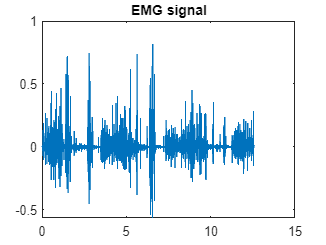

filtered_signal = filter(c2,1,abs(raw_data));

% Grafica de señal original y filtrada

plot(raw_time, raw_data);
title('EMG signal');

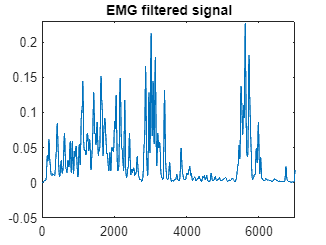


plot(filtered_signal);
title('EMG filtered signal');
xlim([0 7000])
ylim([-0.05 0.23]);

- Mejores resultados con frecuencia de corte normalizada fc/fs

- Utilizar ordenes potencias de 2

### MEDIA MOVIL

% --------------------------------------
WinLength = 64; 
Gain = 100;
% --------------------------------------
MA = movmean(abs(raw_data),WinLength);
subplot(2,1,1);
plot(MA*Gain);
xlim([0 7000])
title('MA of EMG signal');

### RMS MOVIL

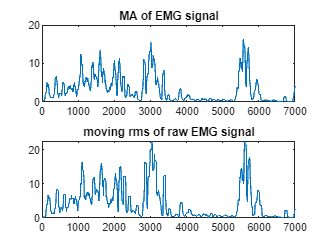

movRMS = dsp.MovingRMS(WinLength);
mRMS = movRMS(raw_data);
subplot(2,1,2);
plot(mRMS*Gain);
xlim([0 7000])
title('moving rms of raw EMG signal');

#     Implementación de FIR "manual"

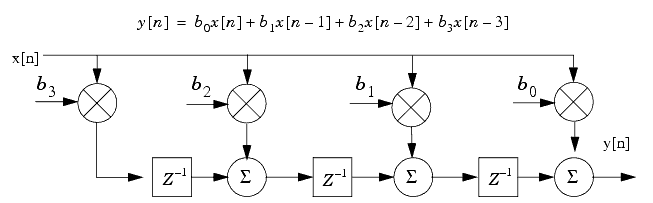

### Sin ventana

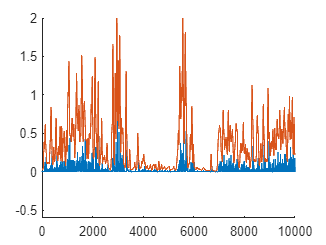

% ---------------------------------
% y(n) = x(n)*c(1)+x(n-1)*c(2)+x(n-2)*c(3) ... +x(n-i)*c(i)
% ---------------------------------
close all
Gain = 10;

x = abs(raw_data);
N = length(x);
C = length(c2);
y = zeros(size(x));

for n=C:N
    for i=1:C
       y(n) = y(n) + x(n-i+1)*c2(i);
    end
end
figure
hold on
plot(abs(raw_data))
plot(Gain*y(length(c2):end))
xlim([0 10000])
ylim([-0.6 2]);
hold off

### Con ventana triangular

close all
% ventaneo
% ---------------------------------
L = 2000; % longitud ventana (recomendado mínimo el doble de la longitud del filtro)
win = [0:1:L/2, L/2:-1:0] /(L/2); % Triangulo de base 2000 y normalizado entre 0 y 1
% win = ones(L,1);

win =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


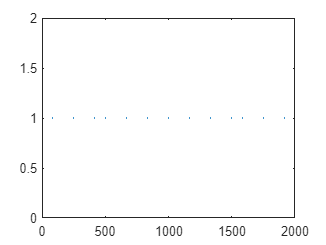

plot(win)

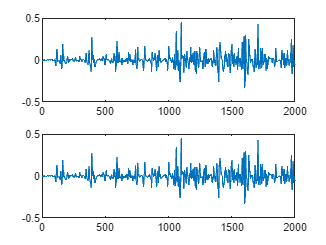


% Aplicar ventana triangular a la señal de entrada
for k=1:(N/L)
    for i=1:L-1
     xwin(k,i) = x(i+(k-1)*L)*win(i);
    end
end
% ---------------------------------
subplot(2,1,1)
plot(xwin(1,:))
subplot(2,1,2)
plot(x(1:L))